# Position Plotter

Daniel Dymond 2021

Plots the position of the ABB-2600-12/1.85 Robot

## User Parameters

% Theta Position for Frames 1 - 7
theta = [0 pi/2 0.6 0 0 0 0];
% a = [0.150 0.900 0.115 0 0 0 0];
% d = [0.445 0 0 0.795 0 0 0.165];
a = [0.150 0.900 0.150 0 0 0 0];
d = [0.445 0 0 0.795 0 0 0.165];

## Computation Script

Obtain Robot Frames and DH data using setupRobot method

% Create Syms for Theta
syms T [1 7];
syms A [1 7];
syms D [1 7];
syms S [1 7];
syms C [1 7];
syms R [3 3];
syms P [3 1];

% [T_subs, DH] = ABB_TEST_CFG();
[T_subs, DH] = ABB_Config();


Create Plot

outputPlot = plot(1);
view(3);
hold on;

Show the Path Preview

outputPlot = drawDesiredPath();

Draw Each link and axis

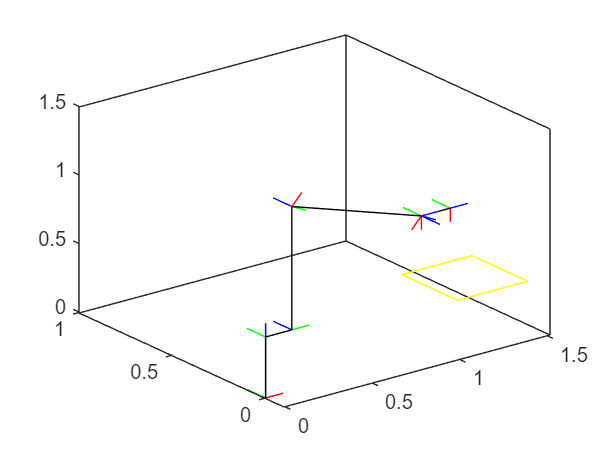

F_0 = eye(4);
outputPlot = drawAxis(F_0);

T_10 = subsSymToT(DH, 1, 0, theta, a, d);
outputPlot = plot3([F_0(1,4) T_10(1,4)], [F_0(2,4) T_10(2,4)], [F_0(3,4) T_10(3,4)], 'black');
outputPlot = drawAxis(T_10);

T_20 = subsSymToT(DH, 2, 0, theta, a, d);
outputPlot = drawAxis(T_20);
outputPlot = plot3([T_10(1,4) T_20(1,4)], [T_10(2,4) T_20(2,4)], [T_10(3,4) T_20(3,4)], 'black');

T_30 = subsSymToT(DH, 3, 0, theta, a, d);
outputPlot = drawAxis(T_30);
outputPlot = plot3([T_20(1,4) T_30(1,4)], [T_20(2,4) T_30(2,4)], [T_20(3,4) T_30(3,4)], 'black');

T_40 = subsSymToT(DH, 4, 0, theta, a, d);
outputPlot = drawAxis(T_40);
outputPlot = plot3([T_30(1,4) T_40(1,4)], [T_30(2,4) T_40(2,4)], [T_30(3,4) T_40(3,4)], 'black');

T_50 = subsSymToT(DH, 5, 0, theta, a, d);
outputPlot = drawAxis(T_50);
outputPlot = plot3([T_40(1,4) T_50(1,4)], [T_40(2,4) T_50(2,4)], [T_40(3,4) T_50(3,4)], 'black');

T_60 = subsSymToT(DH, 6, 0, theta, a, d);
outputPlot = drawAxis(T_60);
outputPlot = plot3([T_50(1,4) T_60(1,4)], [T_50(2,4) T_60(2,4)], [T_50(3,4) T_60(3,4)], 'black');

T_70 = subsSymToT(DH, 7, 0, theta, a, d);
outputPlot = drawAxis(T_70);
outputPlot = plot3([T_60(1,4) T_70(1,4)], [T_60(2,4) T_70(2,4)], [T_60(3,4) T_70(3,4)], 'black');